# Práctica 3 de Percepción y Cognición Audiovisual (Multilayer Perceptron):

## Duda 1:

## En el apartado 1.1.3 nos encontramos con el siguiente y no sabemos si tenemos que escribir lo mismo que a las funciones donde hemos utilizado estas diferentes variables *(z_h, a_h, z_out, y (p))*:

for p = 1: size (in, 2)% pattern loop
    x = in (:, p); % Entrada para la Muestra p
    % Calcula activacion para las neuronas ocultas:
    z_h =; % Suma antes de la sigmoide *
    a_h =; % Activación de las neuronas ocultas *
    a_h =; % Agrega la neurona cuyo valor se siempre igual a uno y que sirve de sesgo a la siguiente capa *
    % Calcula activacion de la neurona de salida:
    z_out =; % Suma antes de la funcionaria de respuesta de la neurona de salida *
    y (p) =; % Calcula respuesta neurona de salida (regresión: identidad - clasificacion: sigmoide logística) *
end

## Respuesta:

Aquí los cálculos son casi iguales a como se calculan estas variables en la función GradientNN. La única diferencia a nivel práctico es que en este bucle cuando se añade 'la neurona cuyo valor es igual a uno' no pondremos un vector de unos con tamaño igual a *y*

ones(size (y))

pero simplemente

a_h = [1; a_h]

o bien

a_h = [ones(size (y (p))); a_h]

Porque encajen bien las dimensiones del que estamos estimando en el bucle.

También fíjate que el término* a_out* dentro de GradientNN, aquí equivale a *y(p)*.

## Duda 2:

## En el apartado 1.2.1 nos pide un valor para el train_frac, qué tenemos que poner? 0.8 como en apartados anteriores?

%% MODIFICAR ----------------------------------------------- -------------------
% Separamos los datos en training y validacion
train_frac =;

## Respuesta: 

Podéis probar con 0.8 y ver si os funciona bien, aquí hay una rango different de valores que deberían funcionar bien. Aquí vale la pena entender que este número correlaciona positivamente con la cantidad de datos que la network tendrá para hacer el training, y negativamente con los datos disponibles para calcular el error con los datos de validación, que sirven para comprobar si se generaliza bien lo que la network ha aprendido. Valores demasiado extremos podrían ser un problema, pero también depende del número de patterns o sea el tamaño de los datos totales, ya que los datos disponibles por el training igual a: *patterns_totals * train_fac.*

## Duda 3:

## Las variables *hidden_units, max_iter y alpha* serán las mismas a lo largo de todos los apartados o éstas cambian? Si cambian qué valores deben tomar para los diferentes apartados?

## Respuesta:

Aquí la idea es probar diferentes rangos de valores intermedios para determinar experimentalmente una combinación de valores óptima para cada caso, que depende de la distribución y la complejidad de los datos. Hay muchas soluciones posibles. Como pone en las instrucciones:

 *Encontrar los Parámetros alpha, hidden_units y max_iter adecuados para lograr que el error baje al mínimo sin que Haya overfitting.*

Según el Oxford dictionary, el overfitting es "la producción de un análisis que se corresponde demasiado cerca o exactamente con un conjunto particular de datos y, por lo tanto, puede no ajustarse a datos adicionales o predecir observaciones futuras de manera confiable". Según el Cambridge Dictionary of Statistics:  “Un modelo sobreajustado es un modelo estadístico que contiene más parámetros de los que pueden justificar los datos.”  La esencia del sobreajuste es haber extraído, sin saberlo, parte de la variación residual (es decir, el ruido) como si esa variación representara la estructura del modelo subyacente (Burnham, Anderson, 2002).

En otras palabras, el modelo recuerda una gran cantidad de ejemplos en lugar de aprender a notar características.

## 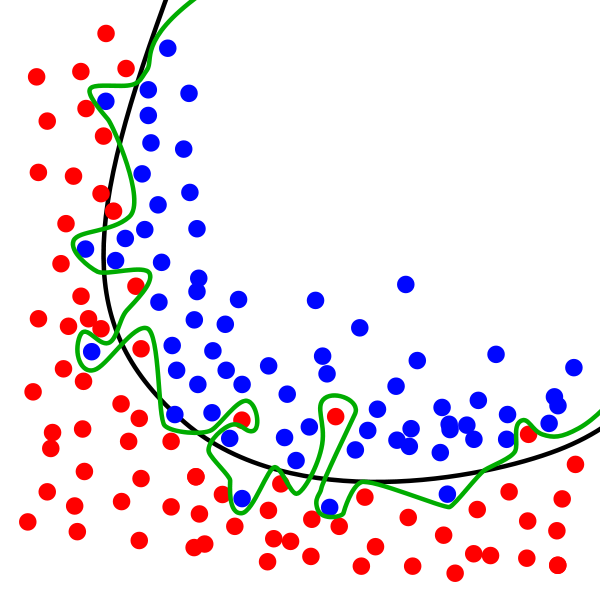

Figura 1. La línea verde representa un modelo sobreajustado (overfitted) y la línea negra representa un modelo regularizado. Si bien la línea verde sigue mejor los datos de entrenamiento, depende demasiado de esos datos y es probable que tenga una tasa de error más alta en los datos nuevos no vistos (datos de validación), en comparación con la línea negra.

## 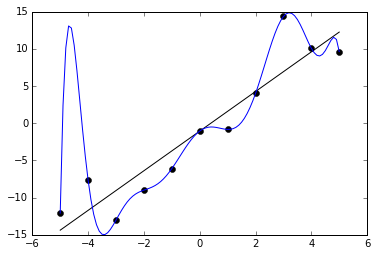

Figura 2. Los datos ruidosos (aproximadamente lineales) se ajustan a una función lineal y una función polinomial. Aunque la función polinomial es un ajuste perfecto, se puede esperar que la función lineal generalice mejor: si las dos funciones se usaran para extrapolar más allá de los datos ajustados, la función lineal debería hacer mejores predicciones.

En general, cuanto más complicada es la función real, y más ruido hay, más hidden_units, y max_iter, y número de datos necesitaremos para aproximarnos bien. Hay que tener en cuenta que lo que realmente queremos conseguir es que el error de validación baje. Si sólo baja el error de training pero no baja el error de validación no sirve. También debemos tener en cuenta que para evitar overfitting, o sea para evitar que baje mucho el error respecto a los datos de training pero que no se generaliza bien a los datos de validación, no queremos poner unos valores de hidden_units e iteraciones demasiado altos. Recuerda que todos estos parámetros se combinan para producir los resultados, y por tanto el valor óptimo de iteraciones dependerá del valor de alpha que has puesto, y de los otros parámetros en cierta medida.

## Sigmoid

Cuidado con la sigmoide. En matlab si queremos que haga una operación elemento por elemento hay que poner .* o ./

Podéis leer más aquí: [https://es.mathworks.com/help/matlab/matlab_prog/array-vs-matrix-operations.html](https://es.mathworks.com/help/matlab/matlab_prog/array-vs-matrix-operations.html)

Para ver esto, puede calcular el producto de dos matrices.

A = [1 3;2 4] 

A =       1     3      2     4 

B = [3 0;1 5] 

B =       3     0      1     5 

A*B 

ans =       6    15     10    20

El producto de matriz anterior no es igual al siguiente producto de elemento.

A.*B 

`ans =       3     0      2    20`

`O sea que para la sigmoide hay que poner:`

g = 1./(1+exp(-z));


Y para la derivada de la sigmoide:

g = sigmoid(z).*(1-sigmoid(z));


Cómo ejemplo, si calculamos 

z=[1 2]
g = 1./(1+exp(-z))

g = 0.7311    0.8808   

En cambio:

1/(1+exp(-z))

Produce un error: 

*Error using  / *

*Matrix dimensions must agree.*

## Generalización del gradiente con respecto a W1

Para calcular el gradiente con respecto a W1 por una muestra, necesitamos filas para cada neurona de entrada, o input de x.

Con 3:

[x(1)*d_h, x(2)*d_h, x(3)*d_h] 


Con 5 

[x(1)*d_h, x(2)*d_h, x(3)*d_h, x(4)*d_h, x(5)*d_h]


Para generalizar para cualquier número de entradas podemos transponer x:

d_h*x'; 

## GradientNN_class

### Actividad de la capa de salida

Para calcular la actividad de la capa de salida hay que aplicar la función sigmoide 

sigmoid(z_out);  


### Evitar errores con 0's e infinitos

Si un número es muy cerca de cero o uno, Matlab va a aproximarlo a cero o a uno. Para calcular el termino delta (d_out) para la capa de salida (en el modelo de classificación) hay que ir con cuidado para evitar errores al dividir por cero cuando Matlab aproxima la actividad de salida a uno.

(a_out - y)./(a_out.*(1-a_out)).*sigmoidGradient(z_out)

Para evitar esto, podemos calcular el termino delta así:

ds = sigmoidGradient(z_out);
dEda = (a_out - y)./(a_out.*(1-a_out));
d_out = dEda.*ds;

Cuando ds nos da 0, para evitar infinitos ponemos el delta de salida a 0.

d_out(ds==0)=0;

## Error Cross-Entropy

### Actividad de la capa de salida

Para calcular la actividad de la capa de salida hay que aplicar la función sigmoide.

Si  la actividad de la capa de salida es muy cerca de cero o uno, Matlab va a aproximarlo a cero o a uno. No podemos calcular log(0).

>>log(0)
ans =
  -Inf

Esto nos daría problemas con la fórmula para calcular el error de una muestra con cross-entropy.

-mean(yp.*log(a_out) + (1-yp).*log(1-a_out) )

Para evitar esto, podemos utilizar el número eps, el número más pequeño que puede calcular Matlab

>>eps
ans =
   2.2204e-16

Si actividad de salida es 1, podemos restar eps. 

 a_out = a_out - eps;

   Si la actividad de salida es 0, podemos sumar eps.

  a_out = a_out + eps; 